# Spontaneous retinal wave analysis

P7 tmem16a cKO and control mice

## load image


%[fname, dname] = uigetfile('M:\Bergles Lab Data\Projects\In vivo imaging\*.tif','Multiselect','on');
[fname, dname] = uigetfile('M:\Bergles Lab Data\Papers\P2ry1\*.tif','Multiselect','on');

[~,~,ext] = fileparts([dname, fname]);

%%tif performance 
if strcmp(ext,'.tif') 
    tic;
    X = loadTif([dname fname],16);
    toc;
elseif strcmp(ext,'.czi')
    tic;
    X = bfLoadTif([dname fname]);
    X = imrotate(X,180);
    toc;
else
    disp('Invalid image format.')
end

Elapsed time is 294.716705 seconds.


## get 10th percentiles

tic;
[dFoF, Fo] = normalizeImg(X, 10, 1); toc;

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 3207.918081 

Bleach correction finished. Subtracting baseline...
Elapsed time is 16.629335 seconds.


 %get Fo and display it

## Set ROI masks and generate signals

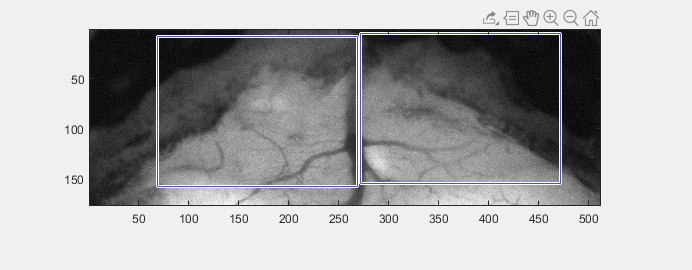

[LSCmask, RSCmask] = getIC_SCmasks(X);


%[SCactivity, bin, bin2] = getSCactivity(dFoF,LSCmask);
%[RSCactivity, Rbin, Rbin2] = getSCactivity(dFoF,RSCmask);
[SCactivity, bin, events] = getSCactivity_new(dFoF,LSCmask);

ans =      1    89


[RSCactivity, Rbin, Revents] = getSCactivity_new(dFoF,RSCmask);

ans =      1   264


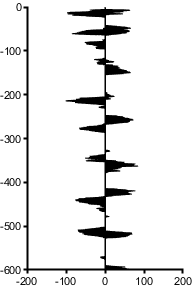

time = [1:1:size(bin,1)]/10;
figure; %plot(sum(-bin,2),-time); hold on; plot(sum(Rbin,2),-time);
l = getRealEvents(bin);
r = getRealEvents(Rbin);
area(-time,-l,'FaceColor','k'); hold on;
area(-time,r,'FaceColor','k');
xlim([-600 0]);
ylim([-200 200])
set(gca,'view',[90 -90])
figQuality(gcf,gca,[4 6]/2);


%
%save([dname 'stats.mat'], 'events','Revents')


%  figure;
%  imagesc([bin2.*SCactivity' Rbin2.*RSCactivity']);
%  colormap(flipud(gray));
%  caxis([0 0.01]);
%  ylim([0 6000]);
%  figQuality(gcf,gca,[4 6]);

## group analysis


% control events
defaultDir = 'F:\Calvin\tmem16a\IC widefield tecta spont\SC wave analysis'

defaultDir = 'F:\Calvin\tmem16a\IC widefield tecta spont\SC wave analysis'

cd(defaultDir);
addpath('196_3 flfl','203_1 tecta flfl','203_3 flfl','208_1 tecta flfl','208_2 flfl','214_1 tecta flfl','235_2 tecta flfl','235_3 flfl','242_1 tecta flfl','242_2 flfl','280_1 tecta flfl','295_1 flfl','326_1 flfl','326_3 flfl','326_2 tecta flfl')

flfl1 = load('196_3stats.mat');
flfl2 = load('203_3stats.mat');
flfl3 = load('208_2stats.mat');
flfl4 = load('235_3stats.mat');
flfl5 = load('242_2stats.mat');
flfl6 = load('326_1stats.mat');
flfl7 = load('326_3stats.mat');

tectaflfl1 = load('203_1stats.mat');
tectaflfl2 = load('208_1stats.mat');
tectaflfl3 = load('214_1stats.mat');
tectaflfl4 = load('235_2stats.mat');
tectaflfl5 = load('242_1stats.mat');
tectaflfl6 = load('280_1stats.mat');
tectaflfl7 = load('326_2stats.mat');

% wave frequency (waves / minute)
flflFreq1 = (length(flfl1.events)+length(flfl1.Revents))/10;
flflFreq2 = (length(flfl2.events)+length(flfl2.Revents))/10;
flflFreq3 = (length(flfl3.events)+length(flfl3.Revents))/10;
flflFreq4 = (length(flfl4.events)+length(flfl4.Revents))/10;
flflFreq5 = (length(flfl5.events)+length(flfl5.Revents))/10;
flflFreq6 = (length(flfl6.events)+length(flfl6.Revents))/10;
flflFreq7 = (length(flfl7.events)+length(flfl7.Revents))/10;

tectaflflFreq1 = (length(tectaflfl1.events)+length(tectaflfl1.Revents))/10;
tectaflflFreq2 = (length(tectaflfl2.events)+length(tectaflfl2.Revents))/10;
tectaflflFreq3 = (length(tectaflfl3.events)+length(tectaflfl3.Revents))/10;
tectaflflFreq4 = (length(tectaflfl4.events)+length(tectaflfl4.Revents))/10;
tectaflflFreq5 = (length(tectaflfl5.events)+length(tectaflfl5.Revents))/8.44;   % slightly less than 10 minute movie b/c of movement
tectaflflFreq6 = (length(tectaflfl6.events)+length(tectaflfl6.Revents))/10;
tectaflflFreq7 = (length(tectaflfl7.events)+length(tectaflfl7.Revents))/10;

conFreq = [flflFreq1,flflFreq2,flflFreq3,flflFreq4,flflFreq5,flflFreq6,flflFreq7];
cKOFreq = [tectaflflFreq1,tectaflflFreq2,tectaflflFreq3,tectaflflFreq4,tectaflflFreq5,tectaflflFreq6,tectaflflFreq7]

cKOFreq =     2.5000    2.1000    2.7000    2.1000    2.9621    2.5000    3.4000



figure;
ylbl1 = 'SC waves per minute';
dim2 = [1 2];
conditions2 = {'Control', 'cKO'};
[fig1 h p1] = compare2(conFreq,cKOFreq,conditions2,ylbl1,dim2)

not normal


fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 58
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   0


p1 = 0.3386

p1

p1 = 0.3386

ylim([0 4])
% wave duration

d1 = {flfl1.events.dur};
d2 = {flfl1.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
flfl1dur = mean([d1,d2]);

d1 = {flfl2.events.dur};
d2 = {flfl3.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
flfl2dur = mean([d1,d2]);

d1 = {flfl3.events.dur};
d2 = {flfl3.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
flfl3dur = mean([d1,d2]);

d1 = {flfl4.events.dur};
d2 = {flfl4.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
flfl4dur = mean([d1,d2]);

d1 = {flfl5.events.dur};
d2 = {flfl5.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
flfl5dur = mean([d1,d2]);

d1 = {flfl6.events.dur};
d2 = {flfl6.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
flfl6dur = mean([d1,d2]);

d1 = {flfl7.events.dur};
d2 = {flfl7.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
flfl7dur = mean([d1,d2]);

conDur = [flfl1dur,flfl2dur,flfl3dur,flfl4dur,flfl5dur,flfl7dur,flfl7dur]

conDur =    18.9000   22.2364   24.0148   19.6800   15.3821   19.1536   19.1536



d1 = {tectaflfl1.events.dur};
d2 = {tectaflfl1.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
tectaflfl1dur = mean([d1,d2]);

d1 = {tectaflfl2.events.dur};
d2 = {tectaflfl3.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
tectaflfl2dur = mean([d1,d2]);

d1 = {tectaflfl3.events.dur};
d2 = {tectaflfl3.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
tectaflfl3dur = mean([d1,d2]);

d1 = {tectaflfl4.events.dur};
d2 = {tectaflfl4.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
tectaflfl4dur = mean([d1,d2]);

d1 = {tectaflfl5.events.dur};
d2 = {tectaflfl5.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
tectaflfl5dur = mean([d1,d2]);

d1 = {tectaflfl6.events.dur};
d2 = {tectaflfl6.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
tectaflfl6dur = mean([d1,d2]);

d1 = {tectaflfl7.events.dur};
d2 = {tectaflfl7.Revents.dur};
d1 = cell2mat(d1);
d2 = cell2mat(d2);
tectaflfl7dur = mean([d1,d2]);

cKODur = [tectaflfl1dur,tectaflfl2dur,tectaflfl3dur,tectaflfl4dur,tectaflfl5dur,tectaflfl6dur,tectaflfl7dur]

cKODur =    16.8400   18.3269   19.5556   18.4810   20.7520   16.5000   16.3824


figure;
ylbl1 = 'SC wave duration (s)';
dim2 = [1 2];
conditions2 = {'Control', 'cKO'};
[fig2 h p2] = compare2(conDur,cKODur,conditions2,ylbl1,dim2)

not normal


fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 60
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   0


p2 = 0.1970

p2

p2 = 0.1970

ylim([0 25])

[CorrP CorrA h] = fdr_BH([p1,p2],0.05)

CorrP =     0.3386    0.3386


CorrA =     0.0500    0.0250


h = 2×1 logical array
   0
   0


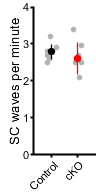

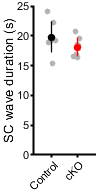


subP = handleTheSubplot({fig1,fig2},[1 2]);

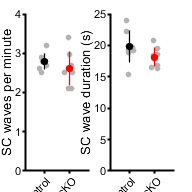

figQuality(subP,gca,[2 2])